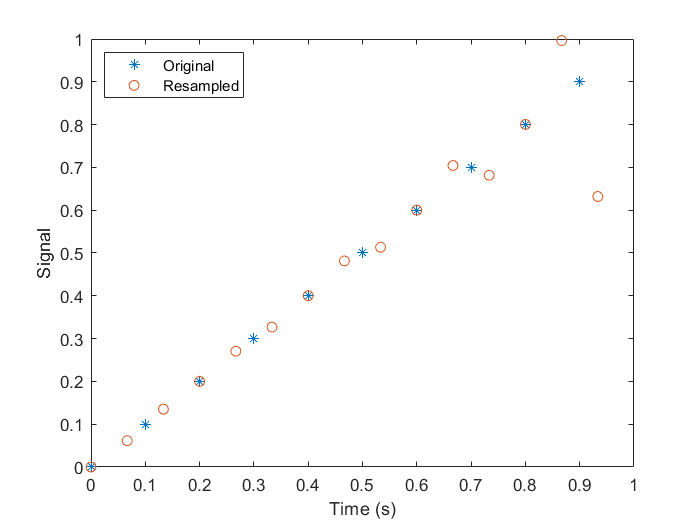

clear all;
close all;
clc;

fs = 10;
t1 = 0:1/fs:1-1/fs;
x = t1;
y = resample(x,3,2);
t2 = (0:(length(y)-1))*2/(3*fs);

plot(t1,x,'*',t2,y,'o')
xlabel('Time (s)')
ylabel('Signal')
legend('Original','Resampled', ...
    'Location','NorthWest')

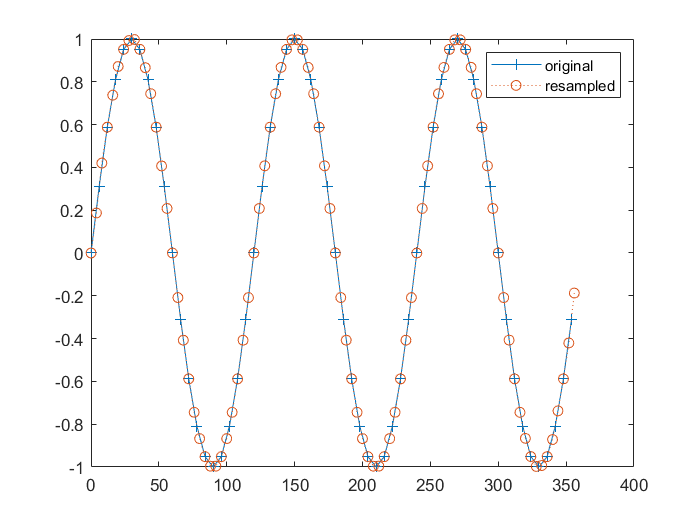

clear all;
close all;
clc;

tx = 0:6:360-3; 
x = sin(2*pi*tx/120);

ty = 0:4:360-2;
% y = sin(2*pi*ty/120)
[y,by] = resample(x,3,2);

plot(tx,x,'+-',ty,y,'o:')
legend('original','resampled')

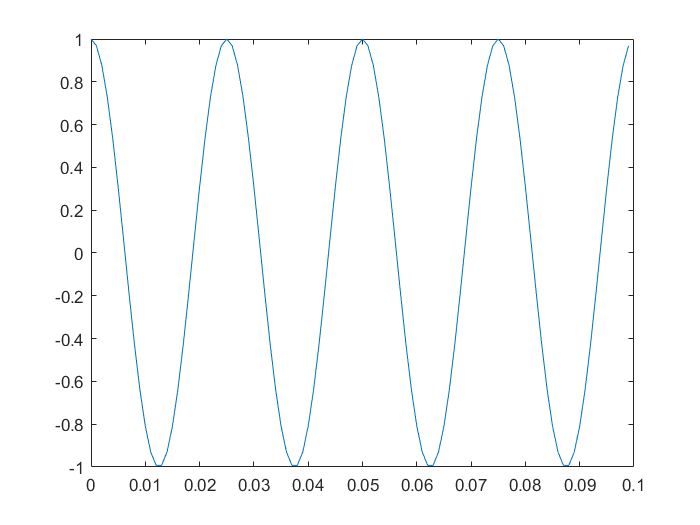

clear all;
close all;
clc;

fs1 = 500;
fs2 = 800;
f_cheating = 1000;
N = 100;
T = 1/f_cheating;
n = 0:N-1;
f = 40;
y = cos(2*pi*f*n*T);
plot(n*T, y);


T_fs1 = 1/fs1;
T_fs2 = 1/fs2;
stem()